# 繪圖軟體應用 第7周(10/23)

dir plot_KL.m


plot_KL.m  



plot_KL.m

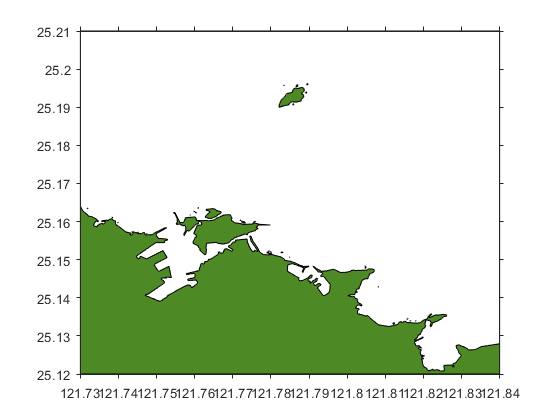

clear;clc;clf
for i=1:56
s=['land_data\land' int2str(i) '.dat'];
c=['land' int2str(i)];
load(s);    %載入檔案
cc=eval(c); %把字串轉成可執行的指令
            %Execute MATLAB expression in text
fill(cc(:,1),cc(:,2),[77/255 137/255 37/255]);hold on; % fill : 塗色
plot(cc(:,1),cc(:,2),'k');hold on;
clear
end
axis('image') %固定圖案的縮放(在縮放視窗時不會變形)
axis([121.73 121.84 25.12 25.21])

set(gca,'tickdir','out','xtick',[121.73:0.01:121.85],'ytick',[25.12:0.01:25.21])
plot([121.73 121.84 121.84 121.73 121.73],[25.12 25.12 25.21 25.21 25.12],'k')  %在figure外面畫框

在圖上左下角放實心白框

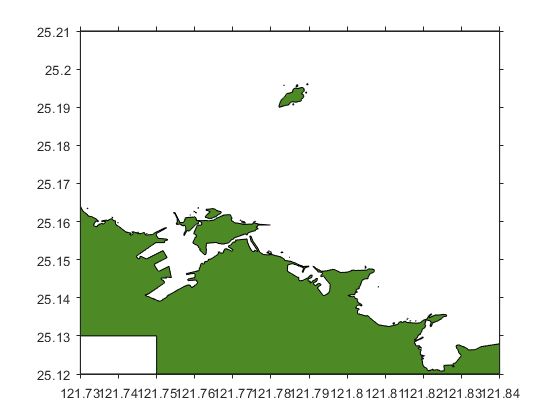

fill([121.73 121.75 121.75 121.73 121.73],[25.12 25.12 25.13 25.13 25.12],'w')

%      本壘    一壘  二壘    三壘    本壘    本壘   一壘  二壘   三壘  本壘   白色

在圖上左下角放空心紅框

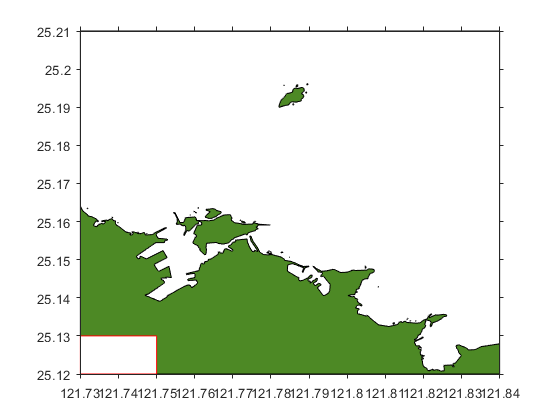

plot([121.73 121.75 121.75 121.73 121.73],[25.12 25.12 25.13 25.13 25.12],'r')

%      本壘    一壘  二壘    三壘    本壘    本壘   一壘  二壘   三壘  本壘   紅色

## 1) 作業2-1

## 用基隆海岸圖，裡面畫圖中圖(台灣)，並用框框標示大圖範圍(基隆)

clear;clc;clf
for i=1:56
s=['land_data\land' int2str(i) '.dat'];
c=['land' int2str(i)];
load(s);    %載入檔案
cc=eval(c); %把字串轉成可執行的指令
            %Execute MATLAB expression in text
fill(cc(:,1),cc(:,2),[77/255 137/255 37/255]);hold on; % fill : 塗色
plot(cc(:,1),cc(:,2),'k');hold on;
clear
end
axis('image') %固定圖案的縮放
axis([121.73 121.84 25.12 25.21])

xlabel('Longitude',"FontSize",12,"FontName",'times')
ylabel('Latitude',"FontSize",12,"FontName",'times')
title('KEELUNG',"FontSize",14)

set(gca,'tickdir','out','xtick',[121.73:0.02:121.85],'ytick',[25.12:0.01:25.21])
set(gca,'LineWidth',4) %坐標軸設定粗細
plot([121.73 121.84 121.84 121.73 121.73],[25.12 25.12 25.21 25.21 25.12],'k')

%% 畫圖中圖
get(gca,'position') % 左 底部 寬度 高度

ans =     0.1300    0.1120    0.7750    0.8130


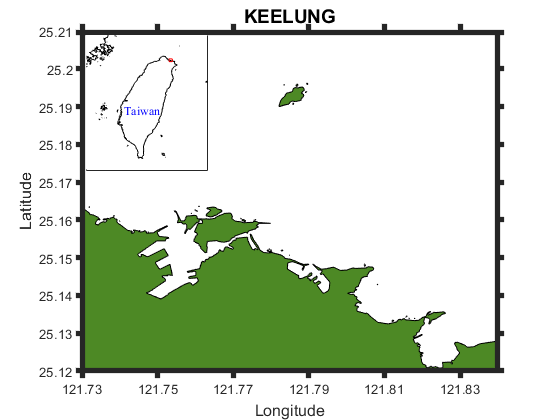

axes('position',[0.062 0.5925 0.4 0.325])
hold on
load plot_KEELUNG.dat %載入檔案
lons = plot_KEELUNG(:,1); %取出經度
lats = plot_KEELUNG(:,2); %取出緯度
plot(lons,lats,'k')
% xlabel('Longitude',"FontSize",16,"FontName",'times')
% ylabel('Latitude',"FontSize",16,"FontName",'times')
% title()
axis('image') %讓圖形在縮放之後不會變形
axis([119 123 21.5 26])
text(120.25,23.5,'Taiwan','FontSize',9,'FontName','times','Color','b')%在圖中標示台灣
% set(gca,'LineWidth',4)%坐標軸設定粗細
set(gca,'XTick',[119:4:123],'YTick',[21.5:5.5:26],'yAxisLocation','right','xticklabels',{})
%改變 X 座標標示 119到123間隔4
%改變 Y 座標標示 21.5到26間隔5.5
set(gca,'xticklabels',{},'yticklabels',{})
plot([121.73 121.84 121.84 121.73 121.73],[25.12 25.12 25.21 25.21 25.12],'r')

%% 存圖
print('map_W71_00781035','-dpng')

## 2) fplot

function plot : 直接匯出函數圖型

`fplot(f,xinterval)`

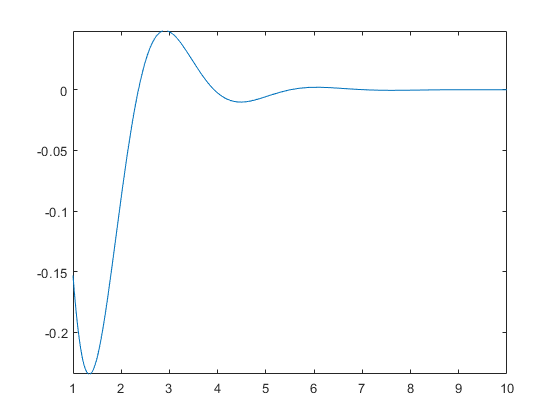

clear;clc;clf
fplot('cos(2*x)./exp(x)',[1,10])

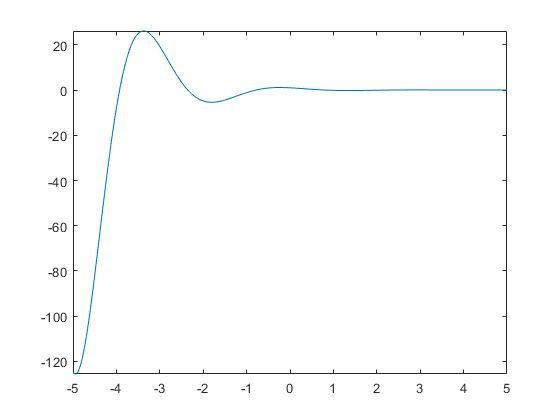

% fplot(@(x) exp(x),[-3 0],'b')
fplot(@(x)cos(2.*x)./exp(x))

## 3) ezplot

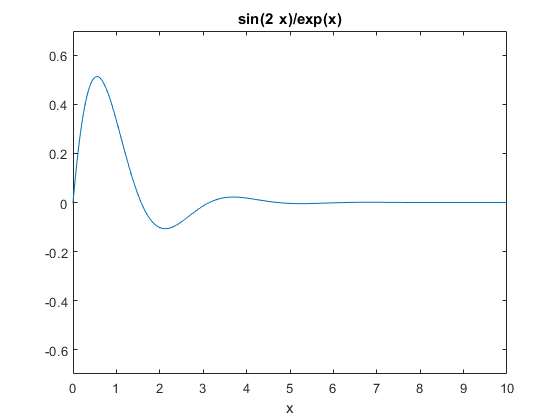

clear;clc;clf
ezplot('sin(2*x)/exp(x)',[0,10,-0.7,0.7])

## 4) 三維繪圖法

### plot3

help graph3d

  Three dimensional graphs.
  
  Elementary 3-D plots.
    plot3      - Plot lines and points in 3-D space.
    mesh       - 3-D mesh surface.
    surf       - 3-D colored surface.
    fill3      - Filled 3-D polygons.
   
  Color control.
    colormap   - Color look-up table.
    caxis      - Pseudocolor axis scaling.
    shading    - Color shading mode.
    hidden     - Mesh hidden line removal mode.
    brighten   - Brighten or darken color map.
    colordef   - Set color defaults.
    graymon    - Set graphics defaults for gray-scale monitors.
    cmpermute  - Rearrange colors in colormap.

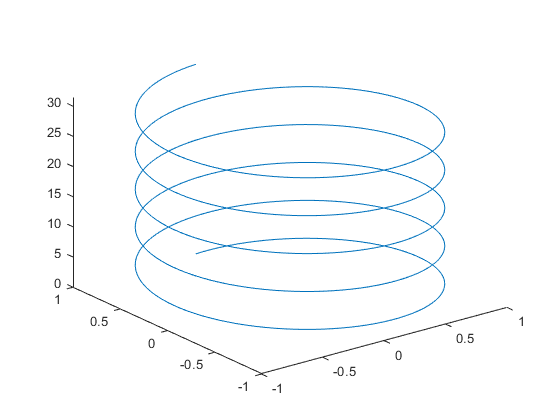

clear;clc;clf
t = 0:pi/50:10*pi;
st = sin(t);
ct = cos(t);
plot3(st,ct,t)

### mesh : Mesh plot

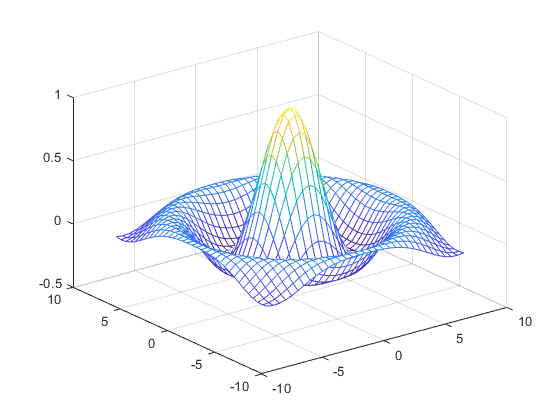

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

### peaks

clear;clc;clf
z1 = peaks; %49*49的矩陣
z2 = peaks(75); %75*75的矩陣
[x y z] = peaks;
whos

  Name       Size            Bytes  Class     Attributes

  x         49x49            19208  double              
  y         49x49            19208  double              
  z         49x49            19208  double              
  z1        49x49            19208  double              
  z2        75x75            45000  double              



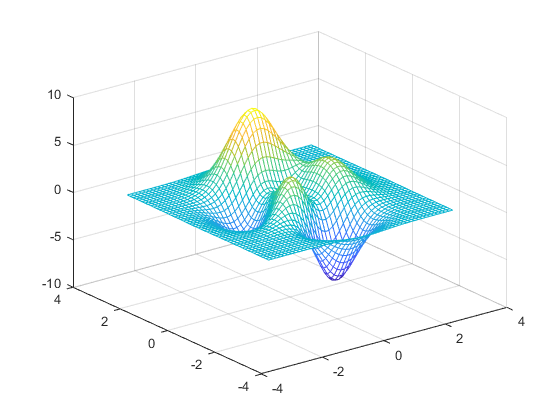

mesh(x,y,z) %網狀圖

### surf

### shading

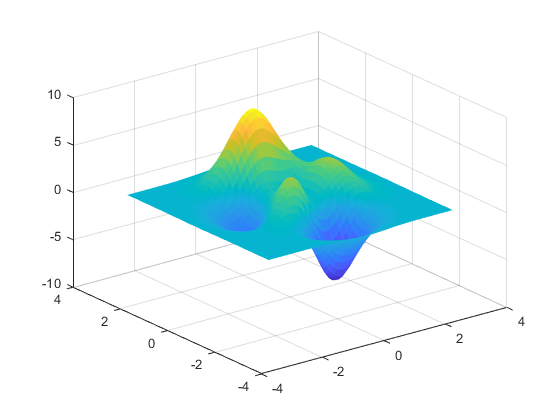

surf(x,y,z)
shading flat

## 5) pcolor 

Pseudocolor plot

pcolor(x,y,z)
colormap('jet')
colorbar('horizontal') %放橫的colorbar
shading interp % 漸進內插(讓圖型平滑一點)
set(gca,'tickdir','out')

## 6)caxis

Set colormap limit

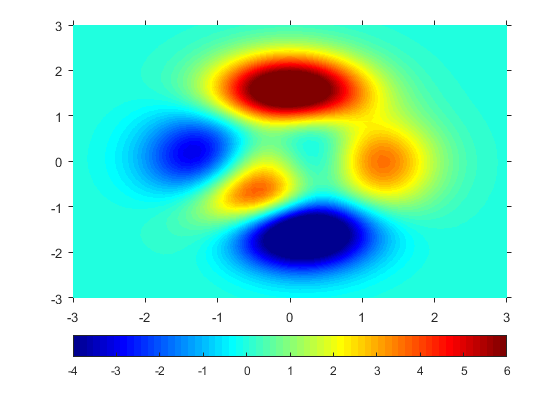

caxis([-4 6])

%把 colormap的區間範圍從 -6 到 8 改成 -4 到 6 

## 7) 作業2-2 

### EX-5-11

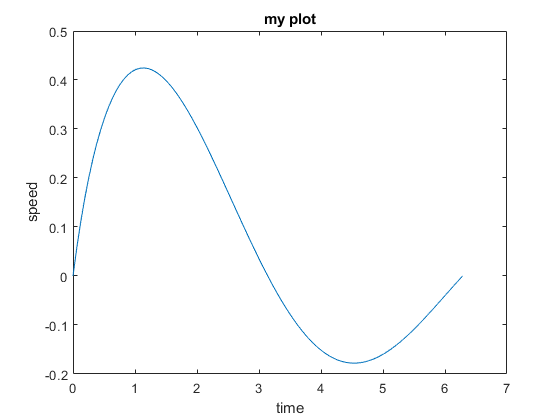

 clear;clc;clf
 x1 = linspace(0,2*pi,100);
 y1 = sin(x1)./(x1+1);
 plot(x1,y1)
 title('my plot');xlabel('time');ylabel('speed')

### EX-5-12

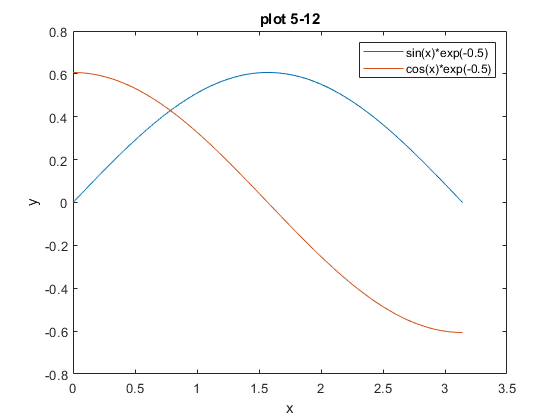

clear;clc;clf
x2 = linspace(0,pi,100);
y21 = sin(x2).*exp(-0.5);
plot(x2,y21)
hold on 
y22 = cos(x2).*exp(-0.5);
plot(x2,y22)
hold off
title('plot 5-12');xlabel('x');ylabel('y');
legend('sin(x)*exp(-0.5)','cos(x)*exp(-0.5)')

### EX-5-14

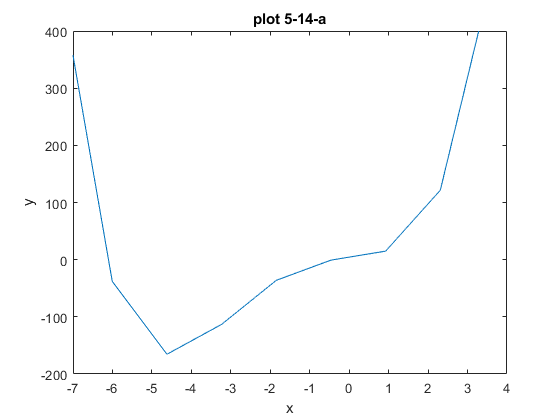

clear;clc;clf
% (a)
figure(1)
ezplot('x^4+6*x^3+7*x+3',[-7,4,-200,400])
title('plot 5-14-a');xlabel('x');ylabel('y')

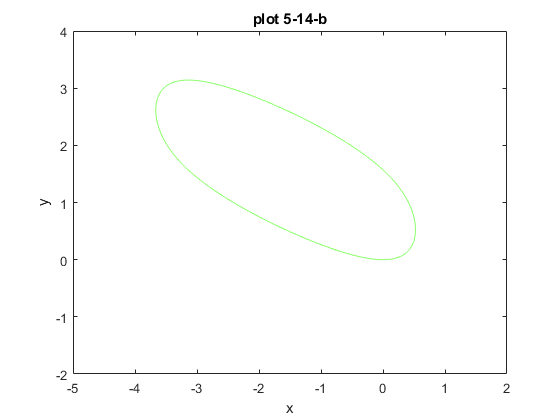

% (b)
figure(2)
ezplot('sin(y)+cos(x+y)-1',[-5,2,-2,4])
title('plot 5-14-b');xlabel('x');ylabel('y')

### EX-5-15

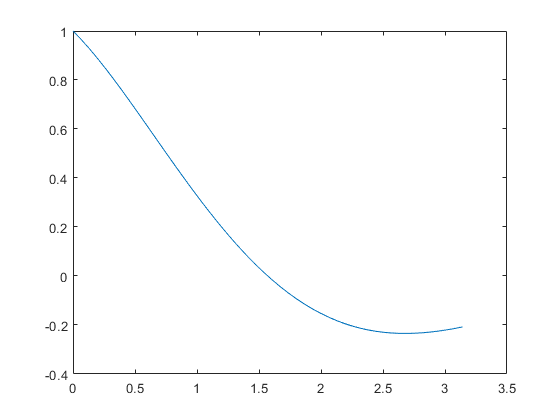

clear;clc;clf
% (a)
 x3 = linspace(0,pi,50);
 y3 = cos(x3).*exp(-0.5.*x3);
 plot(x3,y3)

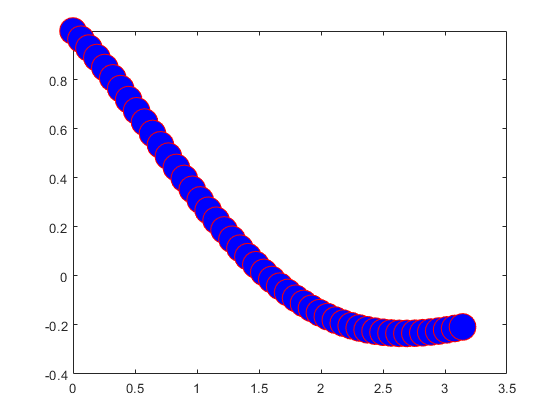

% (b)
 plot(x3,y3,'r--o','MarkerFaceColor','b','MarkerSize',20)

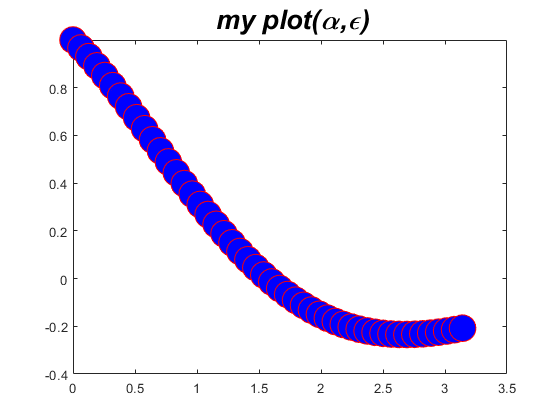

% (c)
 plot(x3,y3,'r--o','MarkerFaceColor','b','MarkerSize',20)
 title('\it my plot(\alpha,\epsilon)','FontSize',20,'FontName','Helvetica')    % 斜體 : 使用\it

                                                              % 字體 : FontName